database = [database_normal,database_seizure,database_interictal];
labels = ["database_normal","database_seizure","database_interictal"];

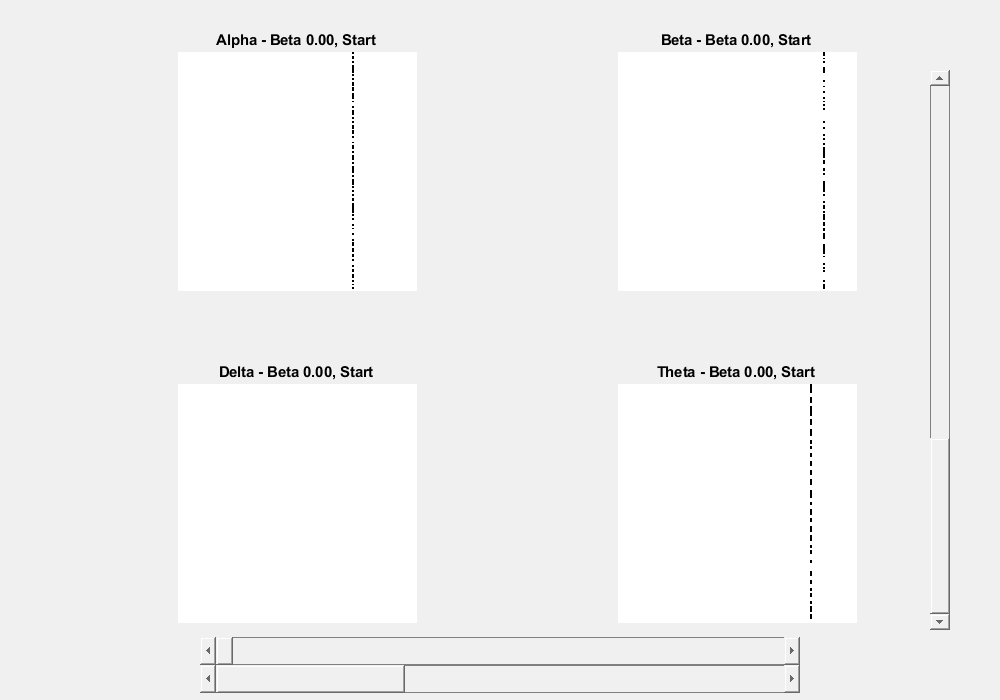

recurrence_plot_viewer3(database);

function recurrence_plot_viewer3(database)
    % Input: database - 11 x N cell array of structs with fields like .alpha, .beta, .delta, .theta

    % Define beta values
    beta_range = [0, 0.125, 0.25, 0.375, 0.5, 0.625, 0.75, 0.875, 1, 1.125, 1.25, 1.375, 1.5, 1.625, 1.75, 1.875, 2, 2.125, 2.25, 2.375, 2.5, 2.625, 2.75, 2.875, 3, 3.125, 3.25, 3.375, 3.5, 3.625, 3.75, 3.875, 4];
    labels = ["database_normal","database_seizure","database_interictal"];
    % Validate database size
 

    N_beta = length(beta_range);
    N_obs = size(database,2);
    N_channels = length(labels);

    % Current indices
    current_beta_index = 1;
    current_obs_index = 1;
    current_database = 1;

    % Create figure
    fig = figure('Name', 'Recurrence Plots Viewer', ...
                 'NumberTitle', 'off', ...
                 'Position', [100, 100, 1000, 700], ...
                 'WindowKeyPressFcn', @keyPressHandler);

    figure(fig); % Ensure focus

    % Axes
    ax1 = subplot(2, 2, 1);
    ax2 = subplot(2, 2, 2);
    ax3 = subplot(2, 2, 3);
    ax4 = subplot(2, 2, 4);

    % === Update Function ===
    function updatePlots()
        instance = database{current_beta_index, current_database};
        beta_val = beta_range(current_beta_index);

        imshow(instance{current_obs_index}.a, 'Parent', ax1, 'Colormap', hot);
        title(ax1, sprintf('Alpha - Beta %.2f, Start %.2f', beta_range(current_beta_index)));

        imshow(instance{current_obs_index}.b, 'Parent', ax2, 'Colormap', hot);
        title(ax2, sprintf('Beta - Beta %.2f, Start %.2f', beta_range(current_beta_index)));

        imshow(instance{current_obs_index}.d, 'Parent', ax3, 'Colormap', hot);
        title(ax3, sprintf('Delta - Beta %.2f, Start %.2f', beta_range(current_beta_index)));

        imshow(instance{current_obs_index}.t, 'Parent', ax4, 'Colormap', hot);
        title(ax4, sprintf('Theta - Beta %.2f, Start %.2f', beta_range(current_beta_index)));
    end

    % Initial plot
    updatePlots();

    % === Sliders ===

    % Beta slider
    uicontrol('Style', 'slider', ...
              'Min', 1, 'Max', N_beta, 'Value', current_beta_index, ...
              'SliderStep', [1/(N_beta-1), 1/(N_beta-1)], ...
              'Units', 'normalized', ...
              'Position', [0.2 0.05 0.6 0.04], ...
              'Callback', @(src, ~) update_beta(round(get(src, 'Value'))));

    % Observation slider
    uicontrol('Style', 'slider', ...
              'Min', 1, 'Max', N_obs, 'Value', current_obs_index, ...
              'SliderStep', [1/(N_obs-1), 1/(N_obs-1)], ...
              'Units', 'normalized', ...
              'Position', [0.2 0.01 0.6 0.04], ...
              'Callback', @(src, ~) update_obs(round(get(src, 'Value'))));

    % Channel slider
    uicontrol('Style', 'slider', ...
              'Min', 1, 'Max', N_channels, 'Value', current_database, ...
              'SliderStep', [1/(N_channels-1), 1/(N_channels-1)], ...
              'Units', 'normalized', ...
              'Position', [0.93 0.1 0.02 0.8], ...
              'Callback', @(src, ~) update_channel(round(get(src, 'Value'))));

    % === Keyboard Controls ===
    function keyPressHandler(~, event)
        switch event.Key
            case 'leftarrow'
                current_obs_index = max(1, current_obs_index - 1);
            case 'rightarrow'
                current_obs_index = min(N_obs, current_obs_index + 1);
            case 'uparrow'
                current_channel_index = min(N_channels, current_channel_index + 1);
            case 'downarrow'
                current_channel_index = max(1, current_channel_index - 1);
            case 'a'
                current_beta_index = max(1, current_beta_index - 1);
            case 'd'
                current_beta_index = min(N_beta, current_beta_index + 1);
        end
        updatePlots();
    end

    % === Update functions for sliders ===
    function update_beta(val)
        current_beta_index = val;
        updatePlots();
    end

    function update_obs(val)
        current_obs_index = val;
        updatePlots();
    end

    function update_channel(val)
        current_channel_index = val;
        updatePlots();
    end
end
